% filename = "testing1D.mat"; % k=6
filename = "testing1D_K10.mat"; % k=10
hasMatFile = isfile(filename);
if (hasMatFile)
    load(filename);
end

### Original signal

Combination of 3 frequency

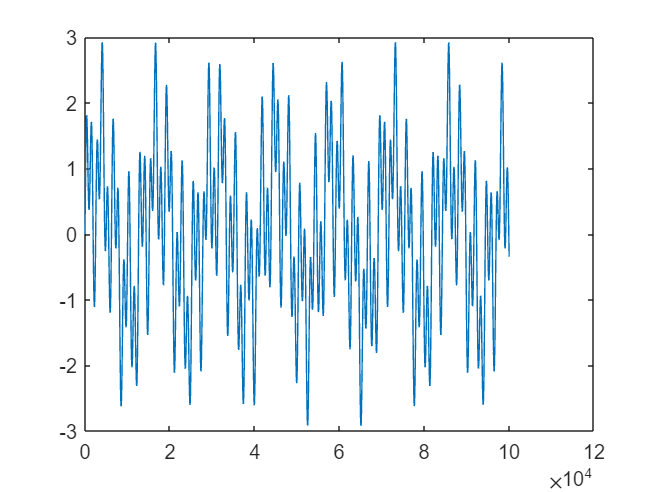

if (~hasMatFile)
    fs = 100;
    t = 0:1/fs:1000;
    f=[2,5,22];
    signal = zeros(1,length(t));
    for fi=f
        signal = signal+sin(t*2*pi*fi);
    end
end
figure('Name','Clear signal');
plot(signal)

### Raw signal

Add noise to signal

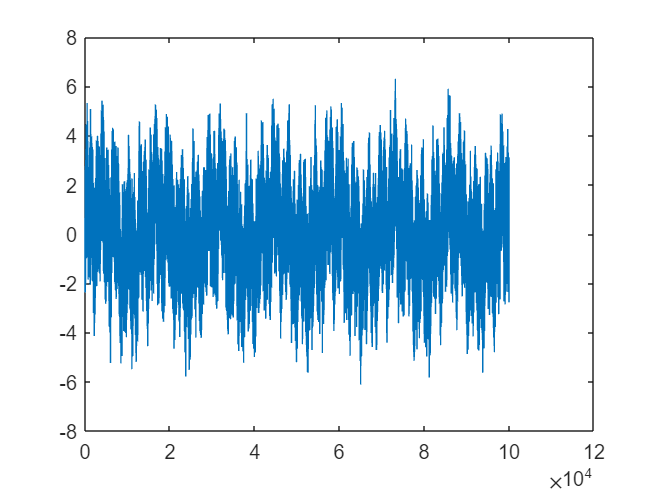

if (~hasMatFile)
    noise = wgn(1,length(t),0);
    raw = signal+noise;
end
figure('Name','Raw signal');
plot(raw);

% psnr
psnr_or = psnr(raw, signal);

### Seperate 5 IMF

if (~hasMatFile)
    % parameters:
    alpha = 5000;       % bandwidth constraint
    tau = 0.25;         % Lagrangian multipliers dual ascent time step
    K = 6;              % number of modes
    DC = 1;             % includes DC part (first mode at DC)
    
    init = 1;           % initialize omegas randomly, may need multiple runs!
    
    tol = K*10^-6;      % tolerance (for convergence)
    
    [u, u_hat, omega]=VMD(raw, alpha, tau, K, DC, init, tol);
end

### Loop for G

G_range = 1:K;
filterType_list = ["wiener","mean","median"];
psnr_v = zeros(K+1,1+length(filterType_list));
psnr_v(1,1) = psnr_or;
for G=G_range

%G = 2; % get G IMR out of K
recontruct = u(1:G,:);
if G>1
    recontruct = sum(u(1:G,:));
end
psnr_v(2,1) = psnr(recontruct, signal);

### Filter noisy signal

for fi=1:length(filterType_list)

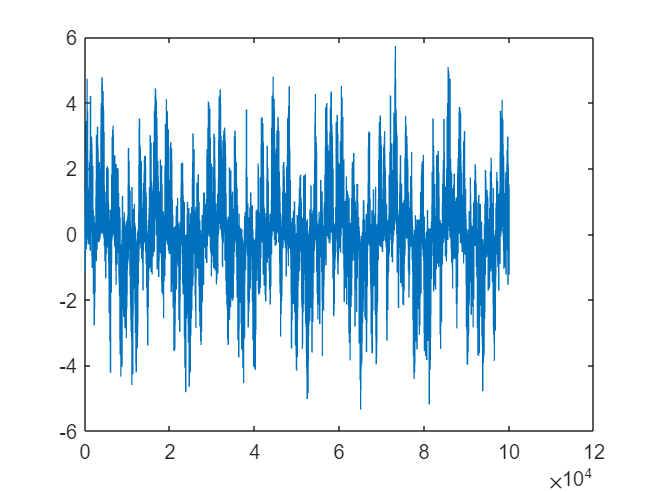

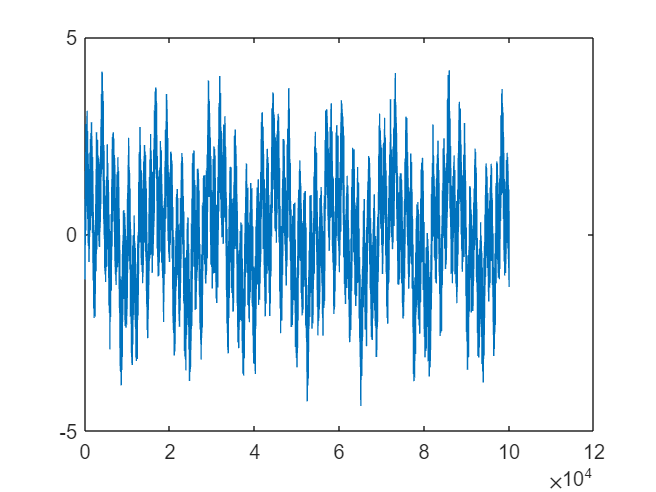

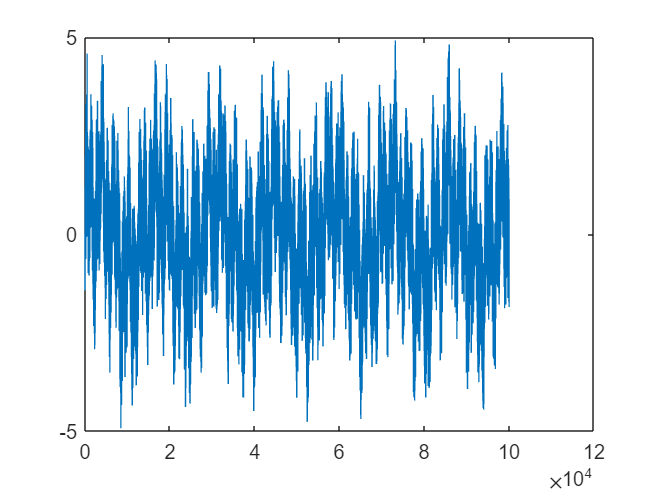

filterType = filterType_list(fi);
filtered_signal =getFiltered(raw,filterType);
figure('Name','filtered signal');
plot(filtered_signal);

psnr_v(1,fi+1) = psnr(filtered_signal, signal);

### Residual calculate + filter

residual = raw - recontruct;
filtered_residual = getFiltered(residual,filterType);
removednoise = filtered_residual+recontruct;
psnr_v(G+1,fi+1) = psnr(removednoise, signal);

end

end

### Plot PSNR

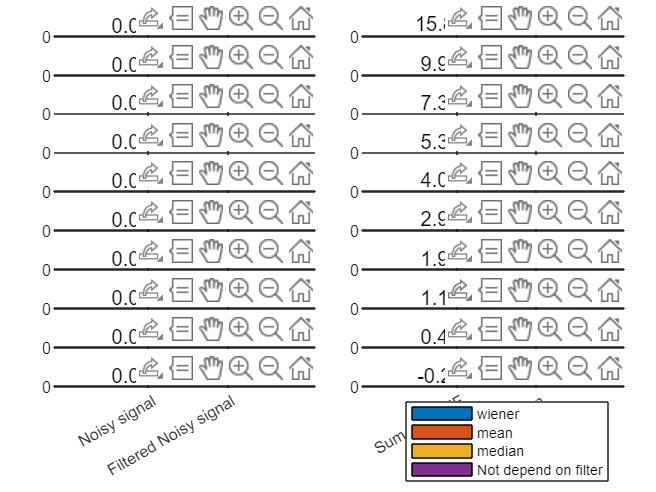

figure('Name','Summary');
sph=[];
tile = tiledlayout(length(G_range),2);
tile.TileSpacing = 'compact';
tile.Padding = 'compact';
for G=G_range
    sph((G-1)*2+1) = nexttile;
    or = zeros
    b1 = bar([]psnr_v(1,:,G),'FaceColor','flat');
    plotNumber(b1);
    set(gca,'xticklabel',{"",""})
    ylabel("PSNR");
    hold on
    bar([psnr_v(1,1,G)]);
    hold off

    sph((G-1)*2+2) = nexttile;
    b2=bar(psnr_v(3:4,:,G),'FaceColor','flat');
    plotNumber(b2);
    set(gca,'xticklabel',{"",""})
    title("G = "+G);
    hold on
    bar([psnr_v(3,1,G)]);
    hold off
end
lenGrange = length(G_range);
set(sph((lenGrange-1)*2+1),'xticklabel',{"Noisy signal","Filtered Noisy signal"});
set(sph((lenGrange-1)*2+2),'xticklabel',{"Sum of "+G+"IMF","Filtered residual+sum"});
legend([filterType_list "Not depend on filter"]);
linkaxes(sph,'y')
ax = axis;
minay = min(min(min(psnr_v)));
maxay = max(max(max(psnr_v)));
gap = (maxay-minay)*0.2;
axis([ax(1:2) minay-gap maxay+gap]);

function plotNumber(b)
    xtips1=[];
    ytips1=[];
    labels1=[];
    for i=1:length(b)
        xtips1 = b(i).XEndPoints;
        ytips1 = b(i).YEndPoints;
        labels1 = string(round(b(i).YData,2));
        for l=1:length(labels1)
            if labels1(l)=="0"
                labels1(l)="";
            end
        end
        text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
        'VerticalAlignment','bottom')
    end
end
function filtered_signal=getFiltered(raw,filterType)
    filtered_signal =[];
    switch filterType
        case "wiener"
            filtered_signal = wiener2(raw);
        case "median"
            filtered_signal = medfilt1(raw);
        case "mean"
            windowSize = 5; 
            b = (1/windowSize)*ones(1,windowSize);
            a = 1;
            filtered_signal = filter(b,a,raw);
    end
end

